# 시뮬레이션 소리 분석

시뮬레이션 소리는 30초짜리, 하나의 소리만 들어가있음

clear, clc, close all

% 시뮬레이션 소리 경로
path0 = "C:/Users/" + getenv('username') +"/Desktop/DCASE2024-Task10-Dataset/simulation/";
loc_name = "loc1/"; % "loc1/";
label_name = "car/left/"; % "car/left/";
loc_name = loc_name + label_name;
train_name = "events-0000-0049.csv";

train_path = path0 + loc_name + train_name;
data_info = readtable(train_path);
len_data = height(data_info);

data_nn = 25; % 1~50(len_data)  % 10;
filepath = path0 + loc_name + data_info.path{data_nn}

filepath = "C:/Users/yeon/Desktop/DCASE2024-Task10-Dataset/simulation/loc1/car/left/event-0024_speed-077.flac"

[sig, fs] = audioread(filepath);
tt = (0:length(sig)-1)/fs;

sig = sig/(max(abs(sig(:))));

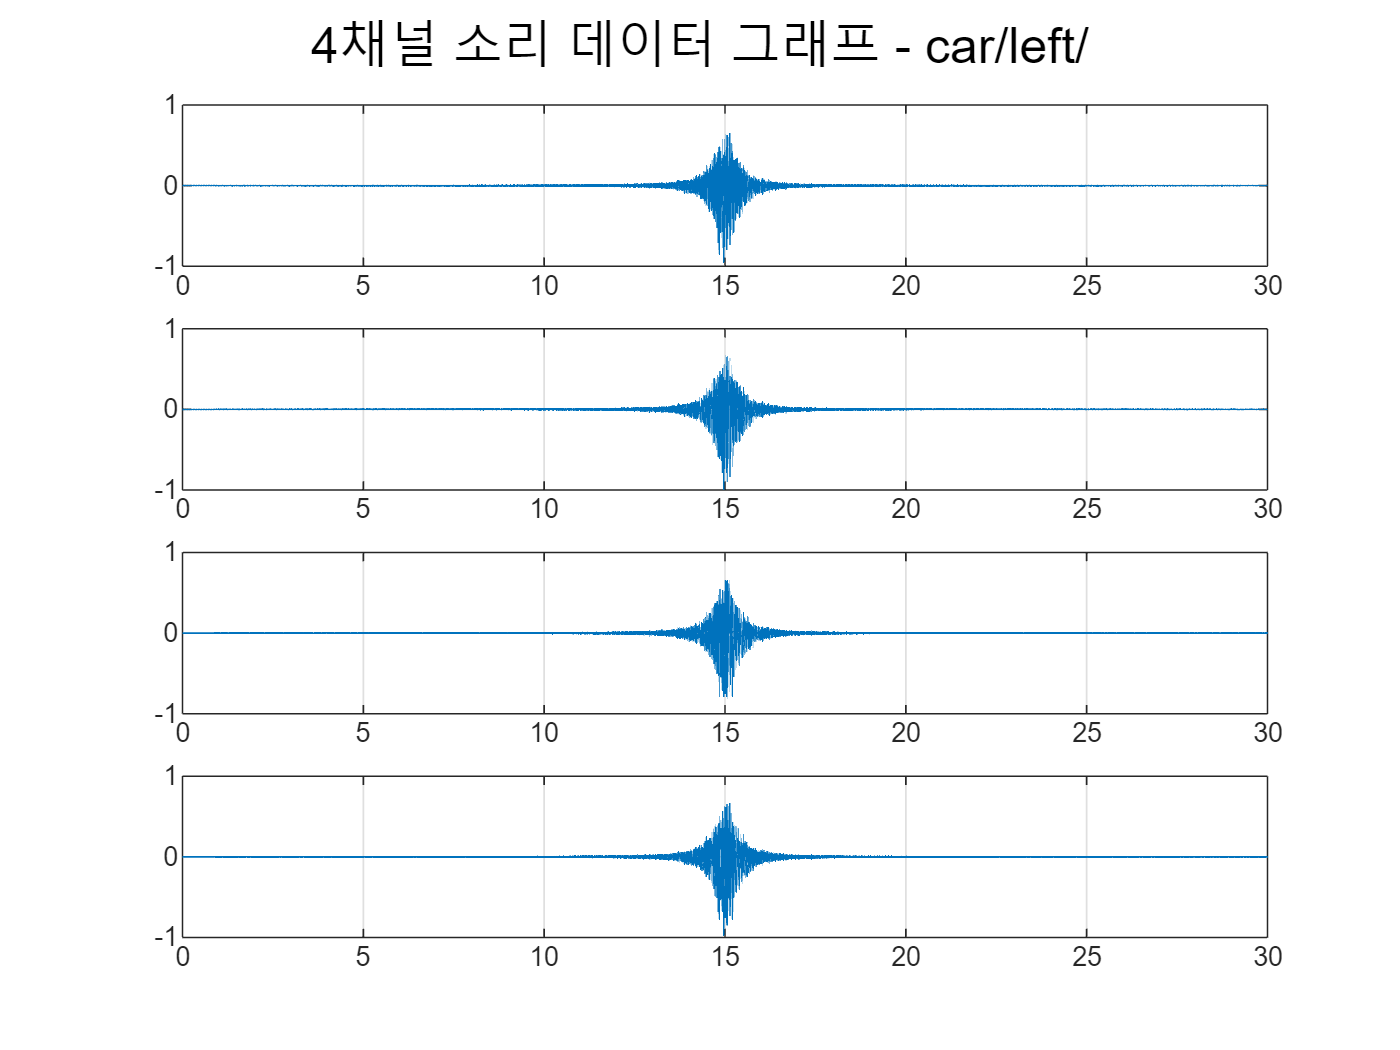

figure("Name", loc_name+"1"), sgtitle("4채널 소리 데이터 그래프 - " + label_name)
for nn = 1:4
    subplot(4,1,nn), plot(tt, sig(:,nn)), grid
end

fframe = 2^10;
delay = fframe/4;
sum_sig = sum_2sig_with_delay(sig, delay);

sthds = {};

tic
parfor nn = 1:6
    sthds{nn} = stHD(sum_sig(:,nn), fs, fframe);
end

'Processes' 프로파일을 사용하여 병렬 풀(parpool)을 시작하는 중...
8개의 워커가 있는 병렬 풀에 연결됨


toc

경과 시간은 52.833241초입니다.


size(sthds{1})

ans =         1024         936


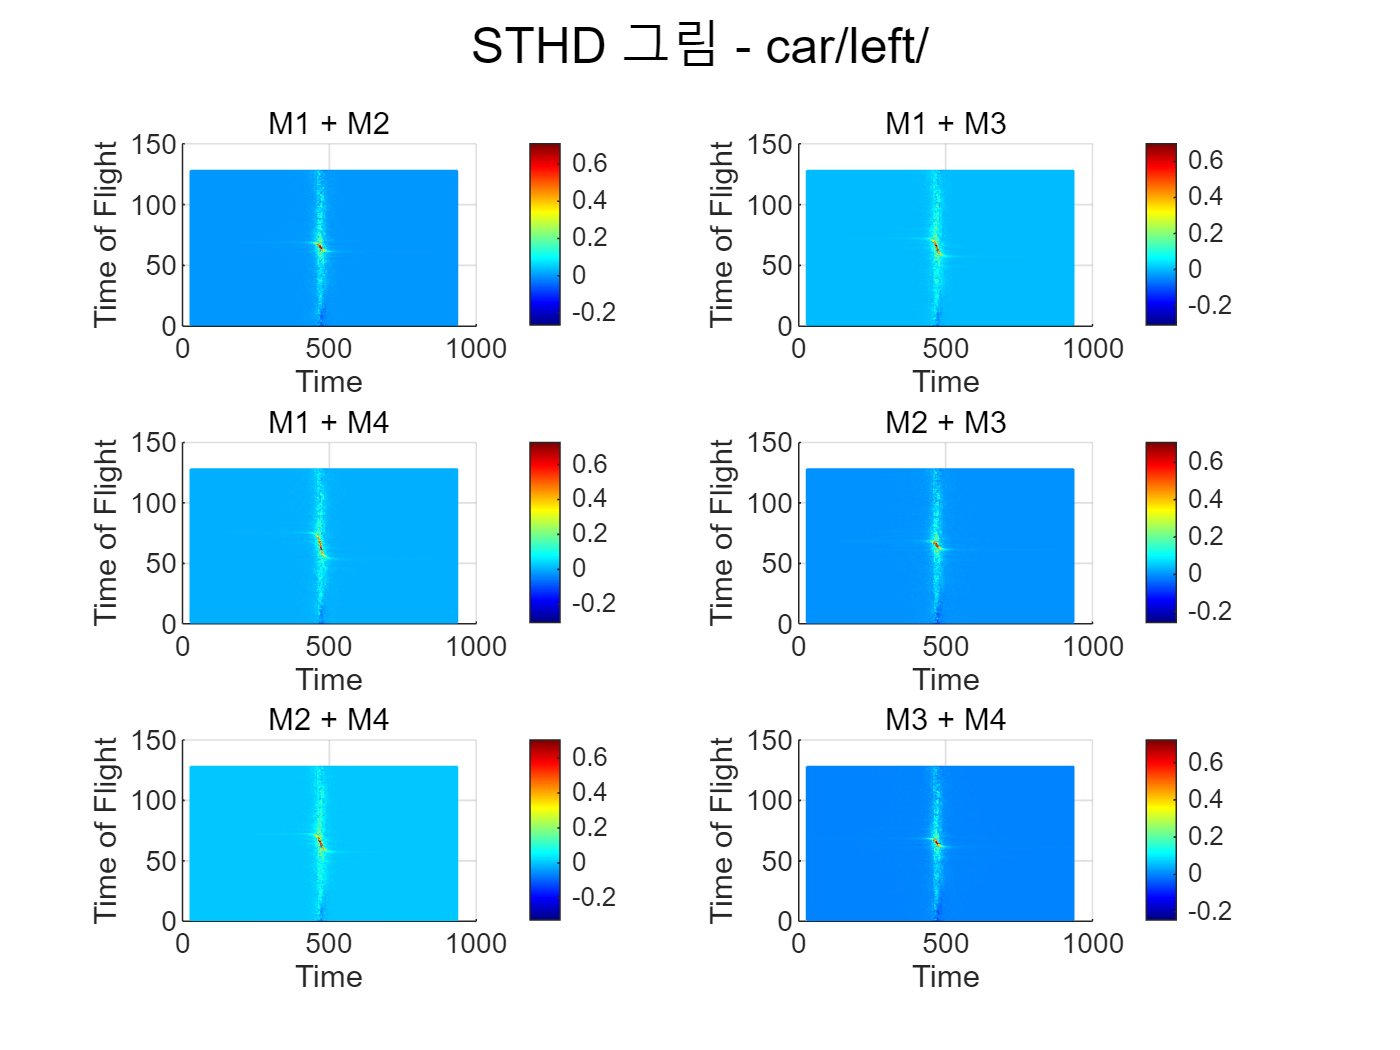

sig_name = {'M1 + M2', 'M1 + M3', 'M1 + M4', 'M2 + M3', 'M2 + M4', 'M3 + M4'};
% mesh_xlim = 1:fframe/2;
mesh_xlim = fframe/4-fframe/16+1:fframe/4+fframe/16;

figure("Name", loc_name+"2"), sgtitle("STHD 그림 - " + label_name)
for nn = 1:6
    sthd = sthds{nn};
    sthd = sthd(mesh_xlim,:);
    
    subplot(3,2,nn),
    mesh(sthd, 'FaceColor', 'flat'), colormap(jet), colorbar, view([0 90]),
    title(sig_name{nn}), xlabel('Time'), ylabel('Time of Flight')%, xlim([1 186])
    % drawnow
end

## Spectrogram 그리기

stft로 계산하고 크기, 제곱을 mag2db를 하면 되나?

stfts = {};
% fframe = 2^14;

tic
parfor nn = 1:4
     S = stft(sig(:,nn)+eps, fs, 'Window', hann(fframe,'periodic'), 'OverlapLength', fframe/2, 'FFTLength', fframe, 'FrequencyRange', 'onesided');      
     stfts{nn} = mag2db(abs(S.^2)+eps);
end
toc

경과 시간은 0.174861초입니다.


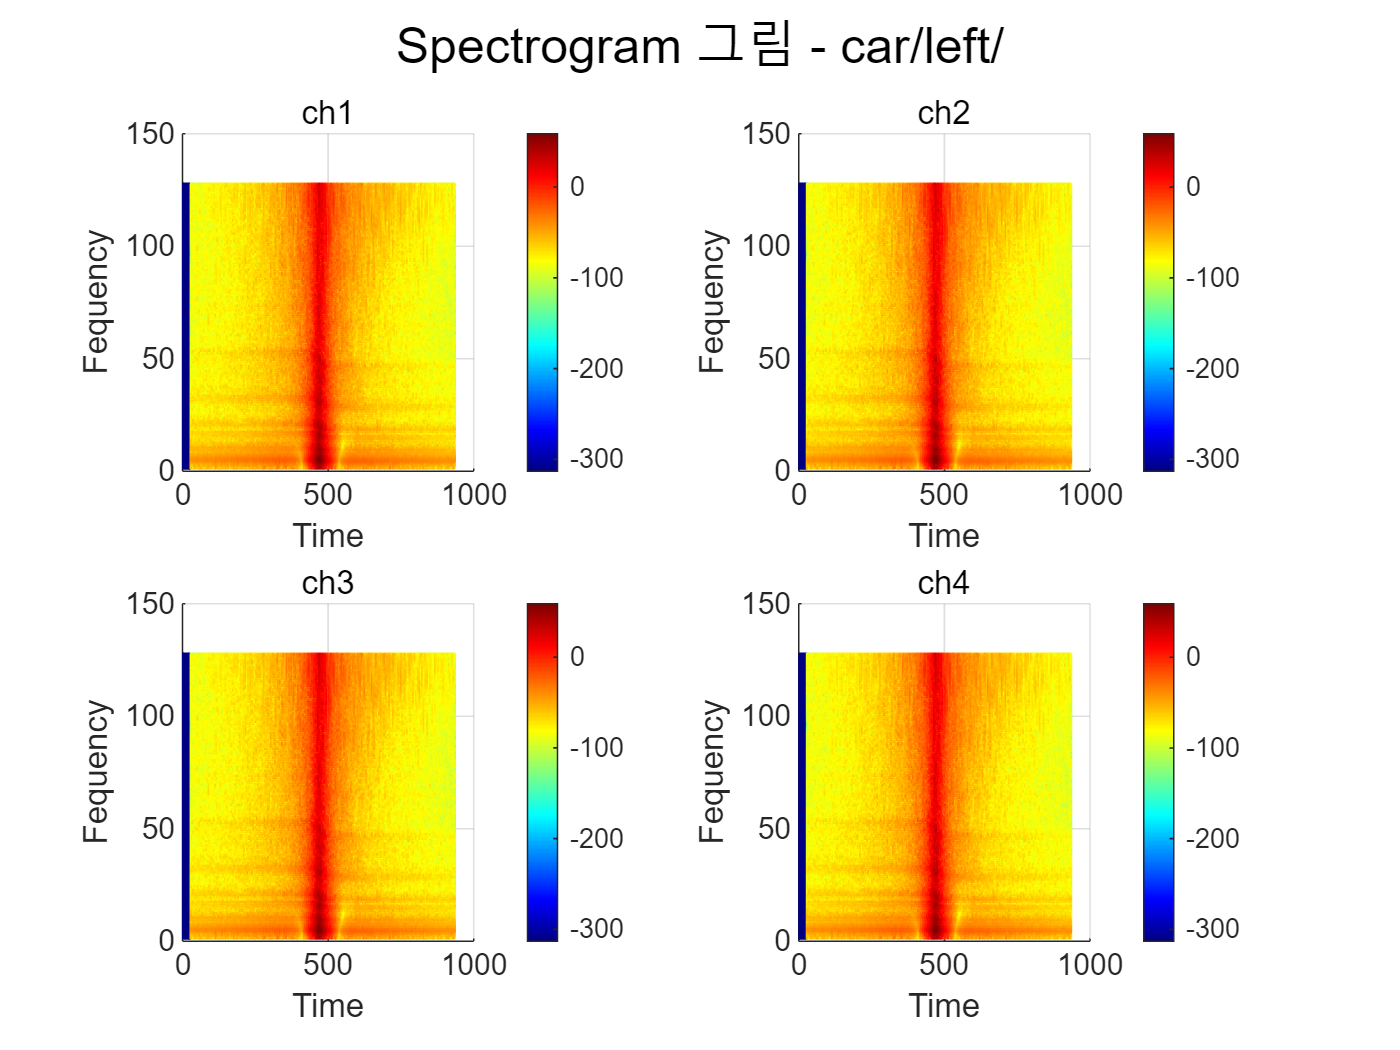

figure("Name", loc_name+"3"), sgtitle("Spectrogram 그림 - " + label_name)
mesh_xlim = 1:fframe/8;

for nn = 1:4    
    subplot(2,2,nn),
    mesh(stfts{nn}(mesh_xlim,:), 'FaceColor', 'flat'), colormap(jet), colorbar, view([0 90]),
    title("ch" + nn), xlabel('Time'), ylabel('Fequency')%, xlim([1 186])
    % drawnow
end

(512/fframe)*fs

ans = 8000

(128/fframe)*fs

ans = 2000

(54/fframe)*fs

ans = 843.7500

(33/fframe)*fs

ans = 515.6250

(22/fframe)*fs

ans = 343.7500